# Behavioral Predictions from the Normalized Tuning Curve

downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
mustHave_2b = {'Extracellular', '_Intensity0d1'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upPDHighC = [];
upPDLowC = [];
upNDHighC = [];
upNDLowC = [];
cnames = {};
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_LowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass || pass_LowC
        continue
    end
    
    cnames{end + 1} = struct_i.cellID;
    %Call the PD of the cell whatever it is in the high contrast condition
    %(round to closest probed direction)
    PD_forNorming = mod(loc.Analysis_Results.PreferredDirection, 360);
    PD = 90;
    orientations = loc.Analysis_Results.Orientation;
    [sortedOs, leaf] = sort(orientations);
    sortedResponses = loc.Analysis_Results.mean_spikesByOrientation(leaf);
    normValue = interp1([sortedOs, 360], [sortedResponses, sortedResponses(1)], PD_forNorming);
    orientations_lowC = loc_LowC.Analysis_Results.Orientation;
    [~, roundedPD_Index] = min(abs(orientations - PD));
    roundedPD = orientations(roundedPD_Index);

    spikes = loc.Analysis_Results.mean_spikesByOrientation./normValue;
    spikes_LowC = loc_LowC.Analysis_Results.mean_spikesByOrientation./normValue;
    
    upPDHighC(end+1) = spikes(orientations == mod(roundedPD,360));
    upPDLowC(end+1) = spikes_LowC(orientations_lowC == mod(roundedPD, 360));
    
    upNDHighC(end + 1) = spikes(orientations == mod(roundedPD + 180, 360));
    upNDLowC(end + 1) = spikes_LowC(orientations_lowC == mod(roundedPD + 180, 360));
end

downPDHighC = [];
downPDLowC = [];
downNDHighC = [];
downNDLowC = [];
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_LowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass || pass_LowC
        continue
    end
    
    cnames{end + 1} = struct_i.cellID;
    
    %Call the PD of the cell whatever it is in the high contrast condition
    %(round to closest probed direction)
    PD_forNorming = mod(loc.Analysis_Results.PreferredDirection, 360);
    PD = 270;
    orientations = loc.Analysis_Results.Orientation;
    [sortedOs, leaf] = sort(orientations);
    sortedResponses = loc.Analysis_Results.mean_spikesByOrientation(leaf);
    normValue = interp1([sortedOs, 360], [sortedResponses, sortedResponses(1)], PD_forNorming);
    orientations_lowC = loc_LowC.Analysis_Results.Orientation;
    [~, roundedPD_Index] = min(abs(orientations - PD));
    roundedPD = orientations(roundedPD_Index);

    spikes = loc.Analysis_Results.mean_spikesByOrientation./normValue;
    spikes_LowC = loc_LowC.Analysis_Results.mean_spikesByOrientation./normValue;
    
    downPDHighC(end+1) = spikes(orientations == mod(roundedPD,360));
    downPDLowC(end+1) = spikes_LowC(orientations_lowC == mod(roundedPD, 360));
    
    downNDHighC(end + 1) = spikes(orientations == mod(roundedPD + 180, 360));
    downNDLowC(end + 1) = spikes_LowC(orientations_lowC == mod(roundedPD + 180, 360));
end


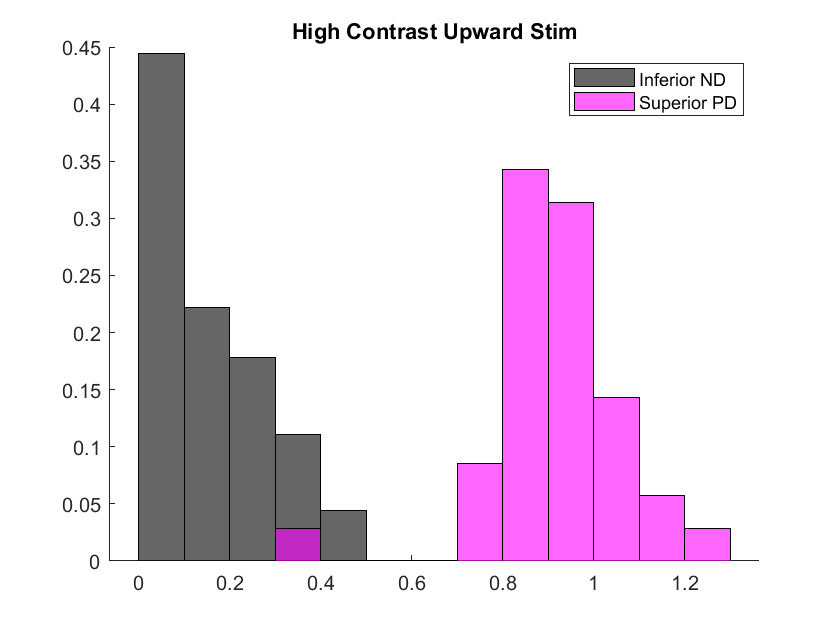

% High contrast upward moving stimulus
figure
title('High Contrast Upward Stim')
hold on
h1 = histogram(upNDHighC, 'FaceColor','k', 'Normalization', 'probability');
h2 = histogram(downPDHighC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'Inferior ND', 'Superior PD'})

diffOfMedians = abs(median(upNDHighC) - median(downPDHighC))

diffOfMedians = 0.8278


labels =  [zeros(1, numel(upNDHighC)), ones(1, numel(downPDHighC))];
scores = [upNDHighC, downPDHighC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.99619


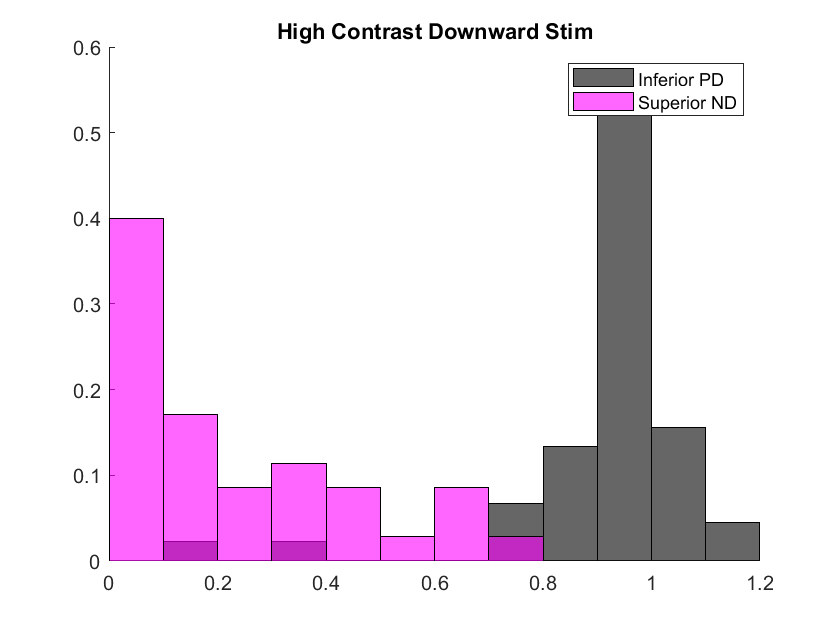


figure
title('High Contrast Downward Stim')
hold on
h1 = histogram(upPDHighC, 'FaceColor','k', 'normalization', 'probability');
h2 = histogram(downNDHighC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'Inferior PD', 'Superior ND'})
xlim([0 1.2])

diffOfMedians = abs(median(upPDHighC) - median(downNDHighC))

diffOfMedians = 0.8360


labels =  [zeros(1, numel(upPDHighC)), ones(1, numel(downNDHighC))];
scores = [upPDHighC, downNDHighC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.98159


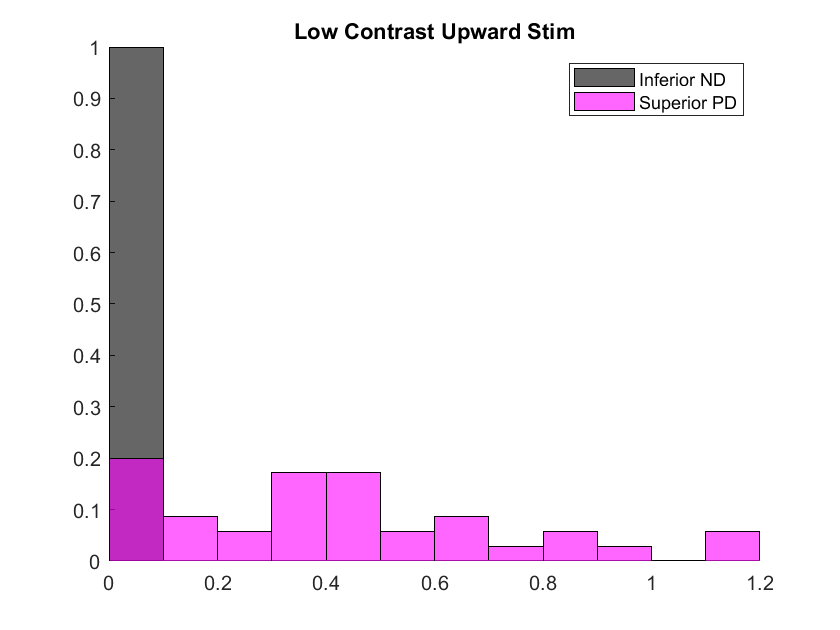


figure
title('Low Contrast Upward Stim')
hold on
h1 = histogram(upNDLowC, 'FaceColor','k', 'normalization', 'probability');
h2 = histogram(downPDLowC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'Inferior ND', 'Superior PD'})
xlim([0 1.2])

diffOfMedians = abs(median(upNDLowC) - median(downPDLowC))

diffOfMedians = 0.3885

labels =  [zeros(1, numel(upNDLowC)), ones(1, numel(downPDLowC))];
scores = [upNDLowC, downPDLowC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.8819


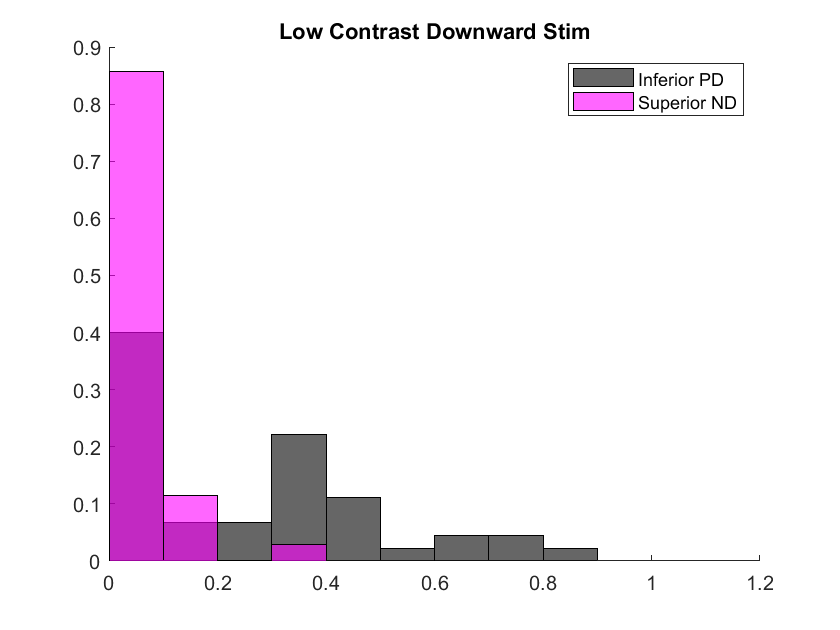

figure
title('Low Contrast Downward Stim')
hold on
h1 = histogram(upPDLowC, 'FaceColor','k', 'normalization', 'probability');
h2 = histogram(downNDLowC, 'FaceColor','m', 'Normalization','probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'Inferior PD', 'Superior ND'})
xlim([0 1.2])

diffOfMedians = abs(median(upPDLowC) - median(downNDLowC))

diffOfMedians = 0.2481

labels =  [zeros(1, numel(upPDLowC)), ones(1, numel(downNDLowC))];
scores = [upPDLowC, downNDLowC];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.76317


## Predictions for Asymmetries

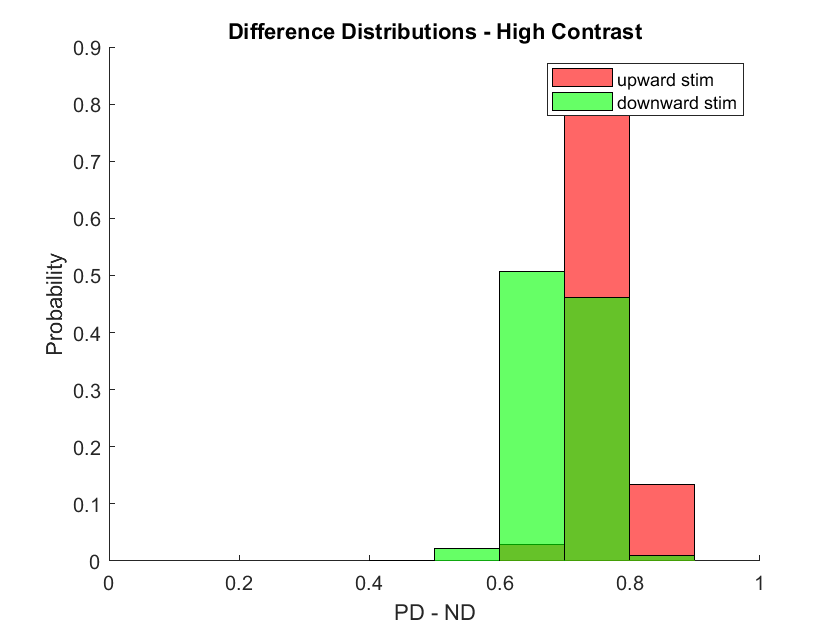


reps = 10000;
results1 = bootstrapSimulation(upNDHighC, 100000);
results2 = bootstrapSimulation(downPDHighC, 100000);
upwardStimHighC_Differences = results2 - results1;

results1 = bootstrapSimulation(upPDHighC, 100000);
results2 = bootstrapSimulation(downNDHighC, 100000);
downwardStimHighC_Differences = results1 - results2;


figure
title('Difference Distributions - High Contrast')
hold on
h1 = histogram(upwardStimHighC_Differences, 'FaceColor', 'r', 'normalization', 'probability');
h2 = histogram(downwardStimHighC_Differences, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'upward stim', 'downward stim'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 1])

differenceOfMedians = median(upwardStimHighC_Differences) - median(downwardStimHighC_Differences)

differenceOfMedians = 0.0682


labels =  [zeros(1, numel(upwardStimHighC_Differences)), ones(1, numel(downwardStimHighC_Differences))];
scores = [upwardStimHighC_Differences, downwardStimHighC_Differences];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.88809


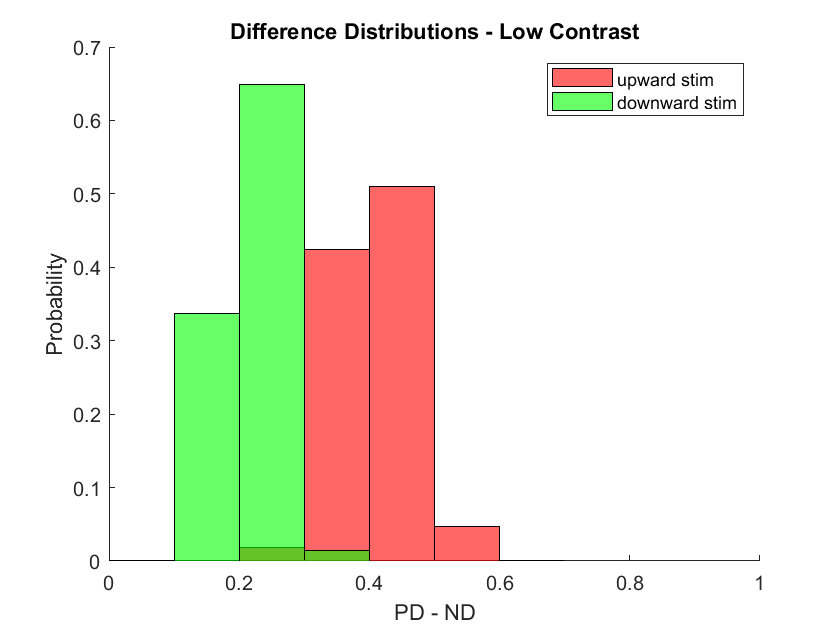


results1 = bootstrapSimulation(upNDLowC, 100000);
results2 = bootstrapSimulation(downPDLowC, 100000);
upwardStimLowC_Differences = results2 - results1;

results1 = bootstrapSimulation(upPDLowC, 100000);
results2 = bootstrapSimulation(downNDLowC, 100000);
downwardStimLowC_Differences = results1 - results2;

figure
title('Difference Distributions - Low Contrast')
hold on
h1 = histogram(upwardStimLowC_Differences, 'FaceColor', 'r', 'normalization', 'probability');
h2 = histogram(downwardStimLowC_Differences, 'FaceColor', 'g', 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'upward stim', 'downward stim'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 1])


differenceOfMedians = median(upwardStimLowC_Differences) - median(downwardStimLowC_Differences)

differenceOfMedians = 0.1924


labels =  [zeros(1, numel(upwardStimLowC_Differences)), ones(1, numel(downwardStimLowC_Differences))];
scores = [upwardStimLowC_Differences, downwardStimLowC_Differences];
[~, ~, ~, AUC] = perfcurve(labels, scores, 1);
AUC = max([AUC, 1-AUC]);
disp(['The ROC AUC for these distributions is ' num2str(AUC)])

The ROC AUC for these distributions is 0.99873


## Asymmetry corresponds to the difference of the differences

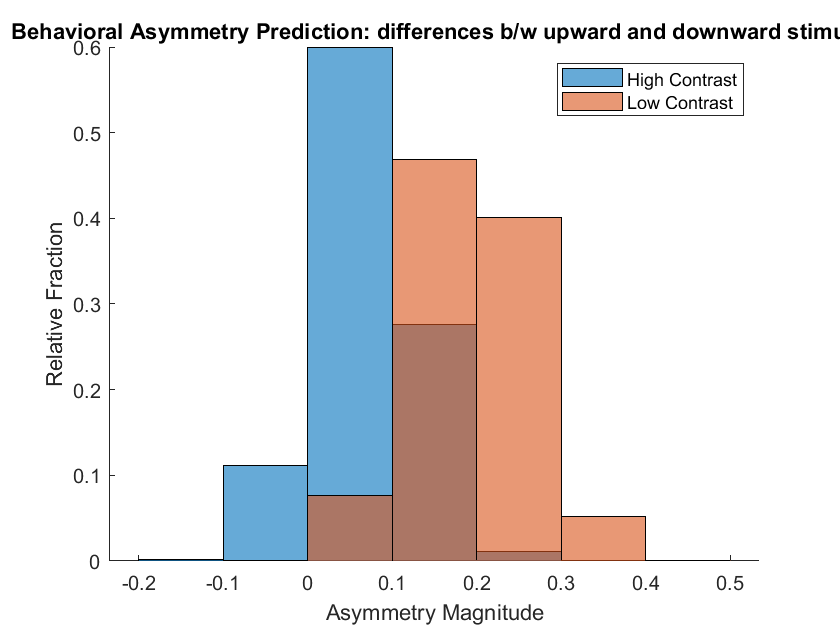


asymmetryDistribution_highC = (upwardStimHighC_Differences - downwardStimHighC_Differences);%./(upwardStimHighC_Differences + downwardStimHighC_Differences);
asymmetryDistribution_lowC = (upwardStimLowC_Differences - downwardStimLowC_Differences);%./(upwardStimLowC_Differences + downwardStimLowC_Differences);

figure
title('Behavioral Asymmetry Prediction: differences b/w upward and downward stimuli')
hold on
h1 = histogram(asymmetryDistribution_highC, 'Normalization', 'probability');
h2 = histogram(asymmetryDistribution_lowC, 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('Asymmetry Magnitude')
ylabel('Relative Fraction')

asymmetryDifference = median(asymmetryDistribution_highC) - median(asymmetryDistribution_lowC)

asymmetryDifference = -0.1243

## Predictions for Change Across Contrast

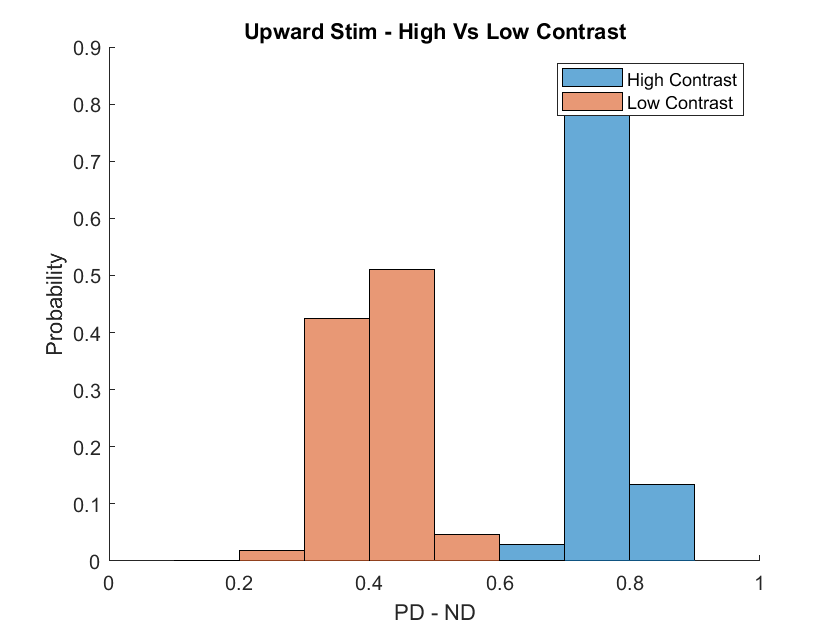

figure
title('Upward Stim - High Vs Low Contrast')
hold on
h1 = histogram(upwardStimHighC_Differences, 'normalization', 'probability');
h2 = histogram(upwardStimLowC_Differences, 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 1])

difference = median(upwardStimHighC_Differences) - median(upwardStimLowC_Differences)

difference = 0.3570

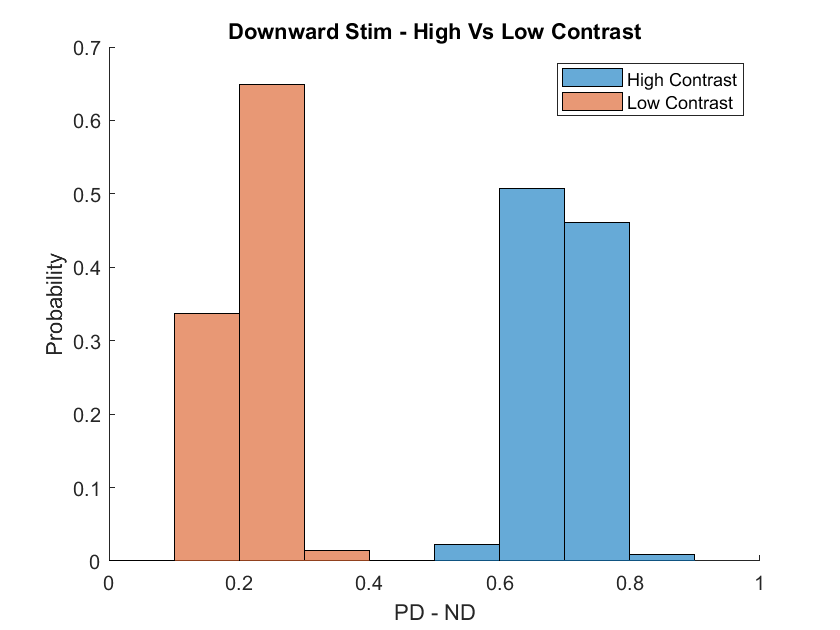


figure
title('Downward Stim - High Vs Low Contrast')
hold on
h1 = histogram(downwardStimHighC_Differences, 'normalization', 'probability');
h2 = histogram(downwardStimLowC_Differences, 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 1])

difference = median(downwardStimHighC_Differences) - median(downwardStimLowC_Differences)

difference = 0.4812

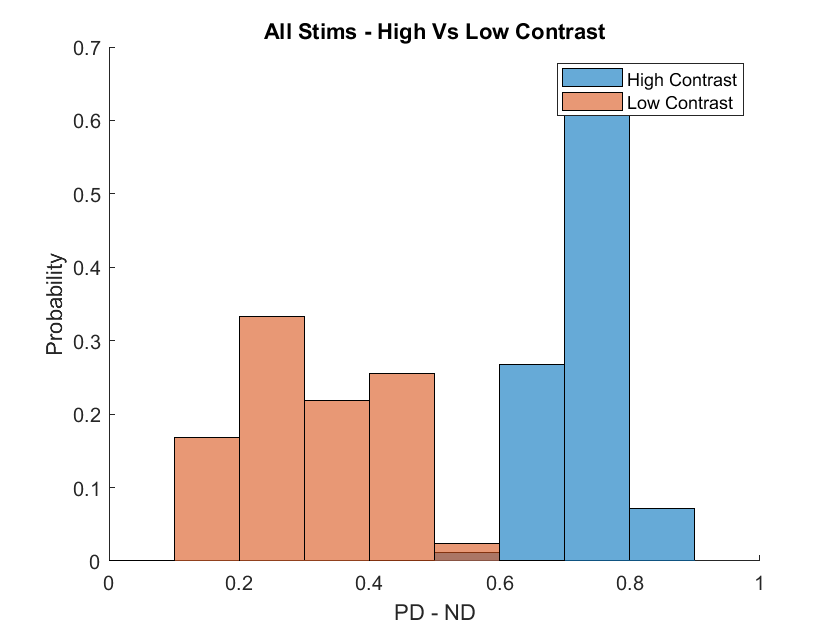


figure
title('All Stims - High Vs Low Contrast')
hold on
h1 = histogram([upwardStimHighC_Differences, downwardStimHighC_Differences], 'normalization', 'probability');
h2 = histogram([upwardStimLowC_Differences, downwardStimLowC_Differences], 'Normalization', 'probability');
h1.BinWidth = 0.1;
h2.BinWidth = h1.BinWidth;
legend({'High Contrast', 'Low Contrast'})
xlabel('PD - ND')
ylabel('Probability')
xlim([0 1])

median([upwardStimHighC_Differences, downwardStimHighC_Differences])

ans = 0.7358

median([upwardStimLowC_Differences, downwardStimLowC_Differences])

ans = 0.2974